close all; clear; clc;

# Test Name

**file name**: Master_Spreadsheet_v1_20190207.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
%p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
%diameter = 0 / 12;
%radius = diameter/ 2;               % [ft]
%area = pi * radius^(2);       % [ft^2]

## P80, 5090, 3blade, 5bat, cont. Jan 28

load('Master_Spreadsheet_v1_20190207.mat');

Q = Master_Spreadsheet_v1_20190207(:,12);                          % [ft.lbf]
T = Master_Spreadsheet_v1_20190207(:,13);                          % [lbf]
rpm = Master_Spreadsheet_v1_20190207(:,16);              % [RPM]
% convert to RPM for plotting purposes
rad = rpm .* (pi/30);                       % [rad/sec]
P_out_W = Master_Spreadsheet_v1_20190207(:,18);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec] 
area = Master_Spreadsheet_v1_20190207(:,6);
diameter = Master_Spreadsheet_v1_20190207(:,5);
p = Master_Spreadsheet_v1_20190207(:,27);


C_T = T ./ (p .* area .* (rad .* (diameter ./ 2)).^2);
C_P = P_out ./ (p .* area .* (rad .* (diameter ./ 2)).^3);
C_Q = Q ./ (p .* area .* (rad .* (diameter ./ 2)).^(2) .* (diameter / 2));

## Plots

The following are standard charts. Remove, add, and edit as needed.

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

figure(6)

plot(time, rot_speed_rpm, time, Max_Acc, 'o');

title('Max acceleration plotted against motor speed')

xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 

legend('Motor RPM', 'Max Accleration'); grid('on');

figure(7)

hold on

yyaxis left

plot(time,Settling_time, 'o-');

ylabel('Settling Time [sec]');

yyaxis right

plot(time, PWM);

ylabel('Motor PWM input');

title('Reaction Time and PWM vs Time');

xlabel('Time [sec]');

grid('minor');

hold off

## Comparing Data to Momentum Theory

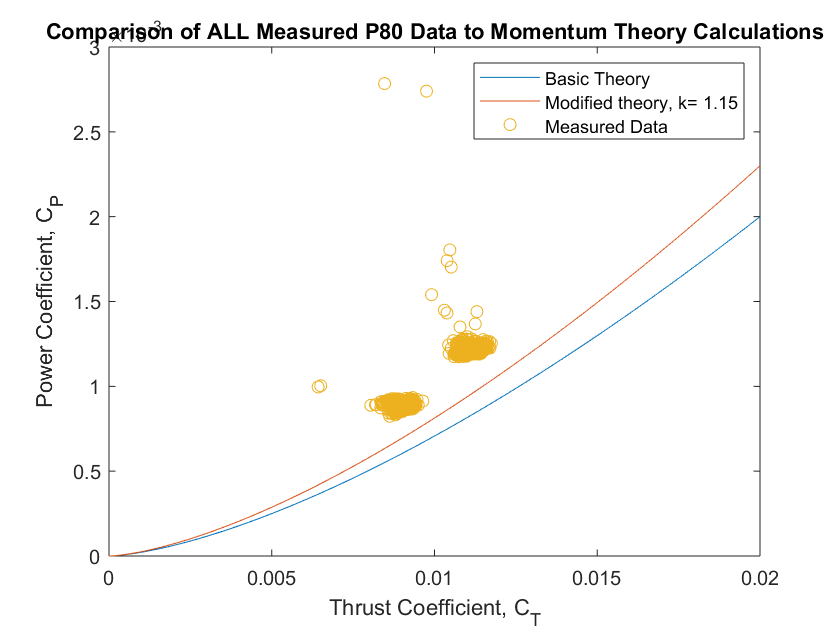

k = 1.15;
C_T_theory = linspace(0, 0.02, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T, C_P, 'o');
title('Comparison of ALL Measured P80 Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.15', 'Measured Data')
xlim([0 0.02]); ylim([0 0.003]);